# Model Predictive Control

close all
clear
clc

addpath("MPCtools/")

**Note: **MPC ex are not difficult from a logic pov, but for a "formulation" one, since the only thing that we have to do is to understand what are our data and how we have to put them in the cauldron. For this reason, this is just a brief summary + exercise. This **doesn't cover all the topics **(for example, I didn't solve problem 1 of lab 7 that is different from problem 1 of lab 6 (solved)), so be careful and baci

Just a quick recap...

MPC is a feedback control technique that at every iteration k solves the constrained optimization problem.

It predicts the system over a finite horizon Hp and it finds optimal U(k) while satisfying constraints, such as input saturation constraints and rate constraints, output constraints, ...

Then it applies only the first element U(1) to the plant

At the next time step k+1, the system state is measured to update the initial condition, the horizon shifts forward, and the optimization is resolved again

## Exercise 

#### Lab 6, problem 1

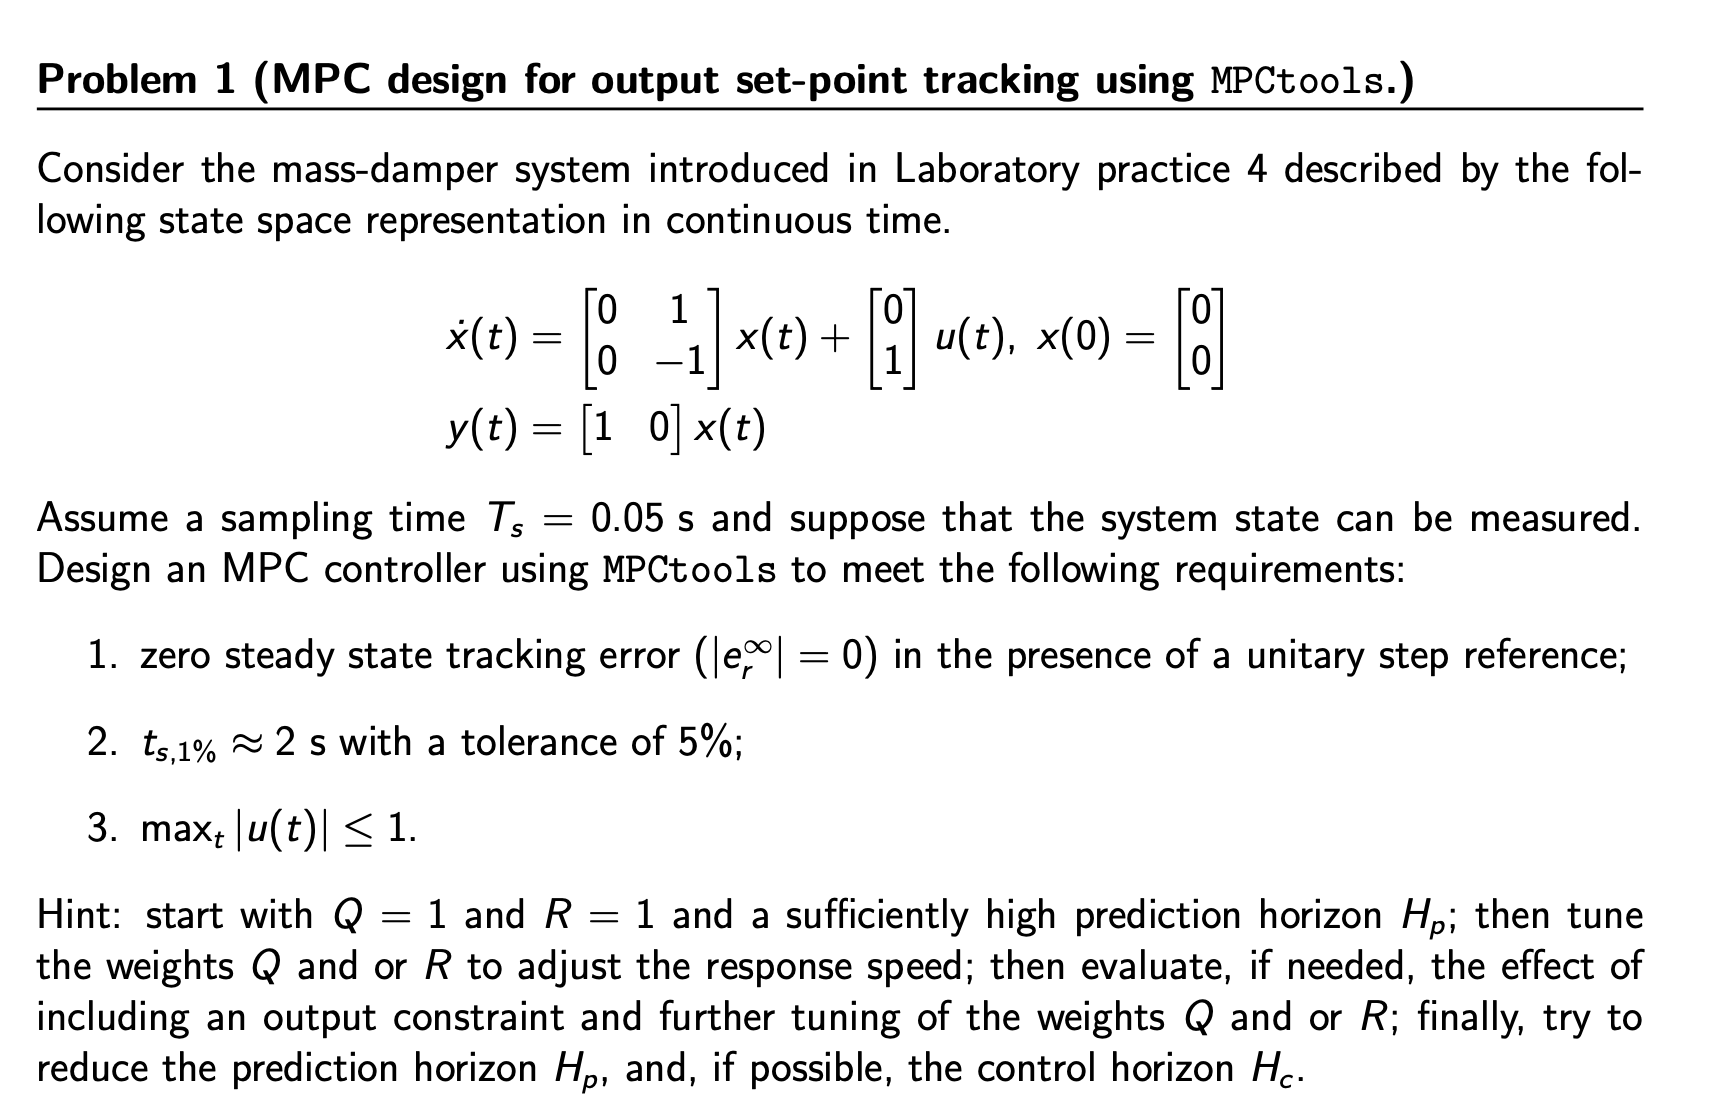

A = [0 1; 0 -1];
B = [0;1];
C = [1 0];
x0 = [0;0];
Ts = 0.05;

sys = ss(A,B,C,0);

% DT system
sys_dt = c2d(sys, Ts, 'zoh');
Ad = sys_dt.a;
Bd = sys_dt.b;
Cd = sys_dt.c;

% MPCtools data

Cy = eye(2); % we measure the state
Cz = Cd;
Dz = 0;
Cc = Cd;
Dc = 0;
Hp = 2/Ts + 5; % we want to "see" at least the settling time interval, the value itself is not important
Hw = 1; % ALWAYS
zblk = 1; % ALWAYS
Hu = Hp; % at the beginning
ublk = 1; % ALWAYS
du_max = [inf]; % we don't have rate constraints
du_min = [-inf];
u_max = [1]; % problem data
u_min = [-1];
z_max = [inf]; % we don't have output constraints
z_min = [-inf]; 
Q = 1; % initial value
R = 1; % initial value
W = []; % ALWAYS
V = []; % ALWAYS
h = Ts; % ALWAYS
cmode = 0; % ALWAYS
solver = 'qp_as'; % ALWAYS

% initialize MPC
md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,zblk, Hu,ublk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,W,V,h, cmode, ...
    solver);

#### Simulation

sys_x = ss(A,B,eye(2),0);
t_sim = 5;
rho = 1;
out = sim('sim_mpc.slx');
figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(rho*1.01, ':r', 'LineWidth',1.2)
yline(rho*0.99, ':r', 'LineWidth',1.2)
xline(2*1.05, ':g', 'LineWidth',1.2)
xline(2*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

**Note: **from now everything is copy/pasted from lab 6 ex

### Tuning

Since our response is "too slow" for our requirements, we need to increase Q or add output limitations. We implement, for the meme, both solutions

Q = 10;

z_max = [1.01]; 
z_min = [-inf];

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,zblk, Hu,ublk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

clear out

out = sim('sim_mpc.slx');
figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(rho*1.01, ':r', 'LineWidth',1.2)
yline(rho*0.99, ':r', 'LineWidth',1.2)
xline(2*1.05, ':g', 'LineWidth',1.2)
xline(2*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

Now we work on Hp and Hc 

We can reduce Hp = 40 but we can't go further decreasing 

Then we can decrease Hu and see until response is still good

Hp = 40;
Hu = 13;

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,zblk, Hu,ublk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

clear out

out = sim('sim_mpc.slx');
figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(rho*1.01, ':r', 'LineWidth',1.2)
yline(rho*0.99, ':r', 'LineWidth',1.2)
xline(2*1.05, ':g', 'LineWidth',1.2)
xline(2*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')
